# First-order example

Open-loop transfer function

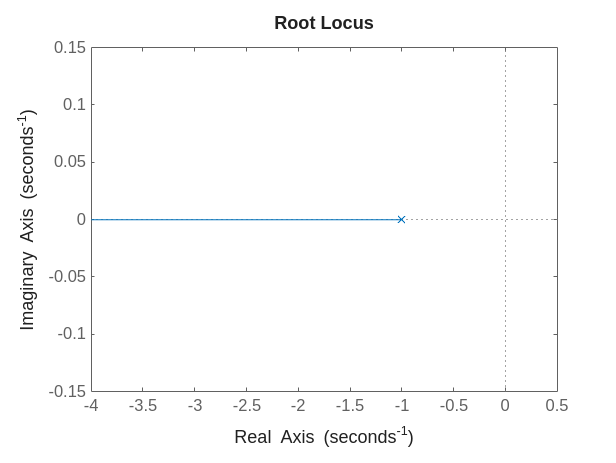

L = tf(1,[1 1])
figure(1);
clf();
rlocus(L)

## Choose a gain from the graph

Where do you want to place the closed loop pole?

K = 2;

Check the closed-loop response.  Does it match with what the root locus predicted?

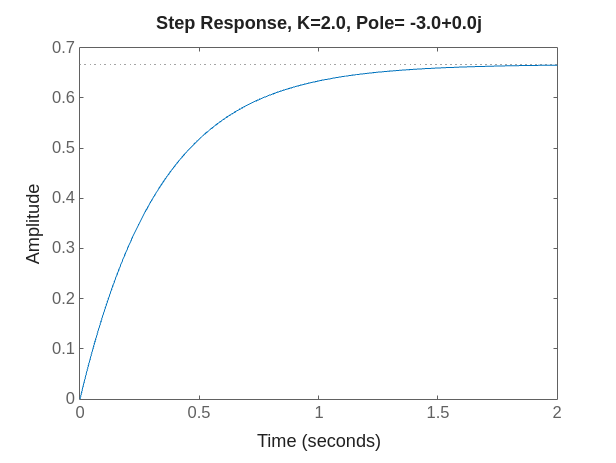

T = feedback(K*L,1);
[wn,z,p] = damp(T);
figure(2);
clf();
step(T)
title(sprintf('Step Response, K=%.1f, Pole= %.1f%+.1fj',K,real(p),imag(p)));

## Second-order example

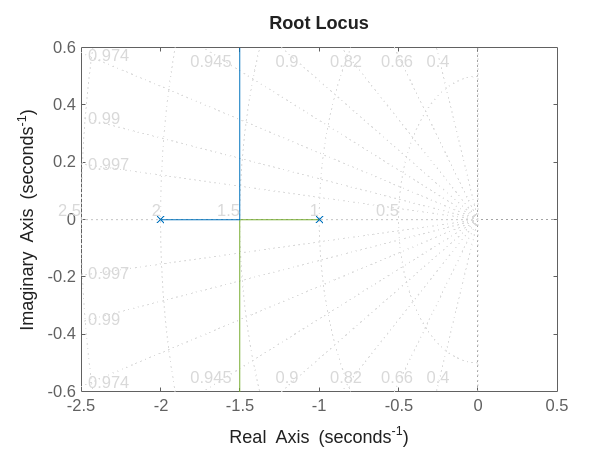

L = tf(1,conv([1 1],[1 2]));
figure(1);
clf();
rlocus(L)
sgrid

## Choose gain from the graph

Where do you want to place the closed loop pole?s

K = 10;

Check the closed-loop response.

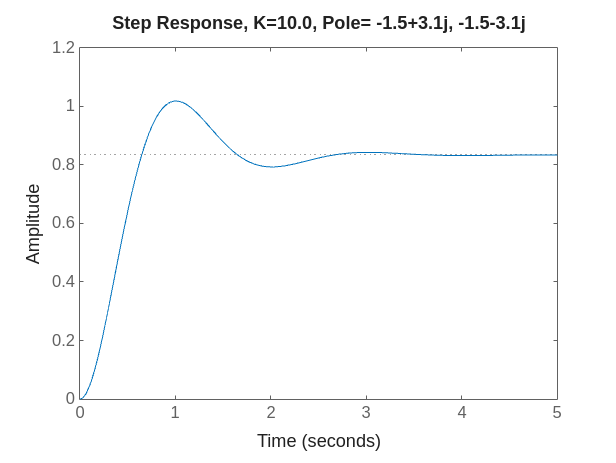

T = feedback(K*L,1);
[wn,z,p] = damp(T);
figure(2);
clf();
step(T)
title(sprintf('Step Response, K=%.1f, Pole= %.1f%+.1fj, %.1f%+.1fj',K, ...
    real(p(1)),imag(p(1)),real(p(2)),imag(p(2))));

## Third-order example to illustrate system that can be pushed unstable

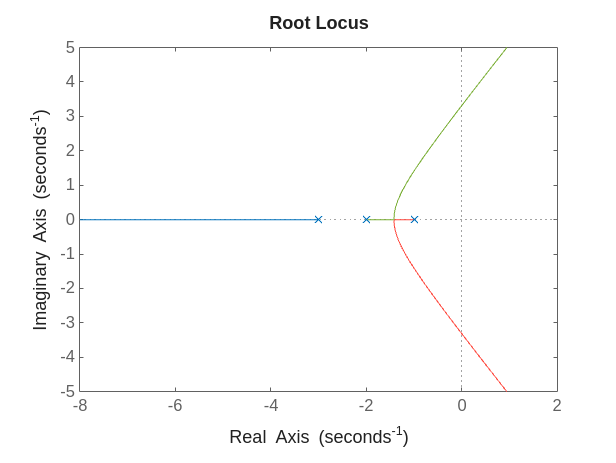

L = tf(1,conv([1 1],conv([1 2],[1 3])));
figure(1);
clf();
rlocus(L)

## Choose gain from the graph

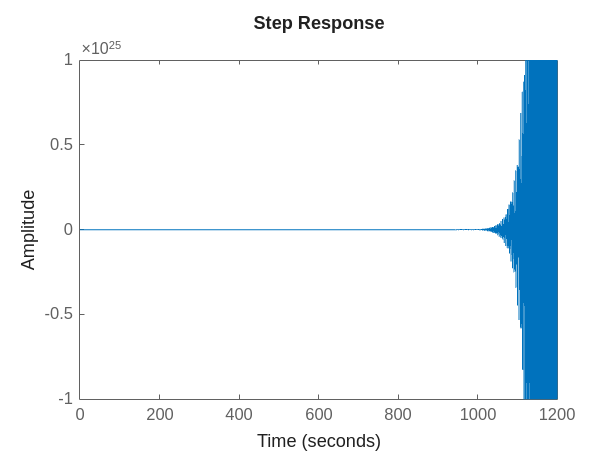

K = 65;
T = feedback(K*L,1);
[wn,z,p] = damp(T);
figure(2);
clf();
step(T)

%title(sprintf('Step Response, K=%.1f, Pole= %.1f%+.1fj, %.1f%+.1fj',K, ...
%    real(p(1)),imag(p(1)),real(p(2)),imag(p(2))));

## Second Order with a Zero

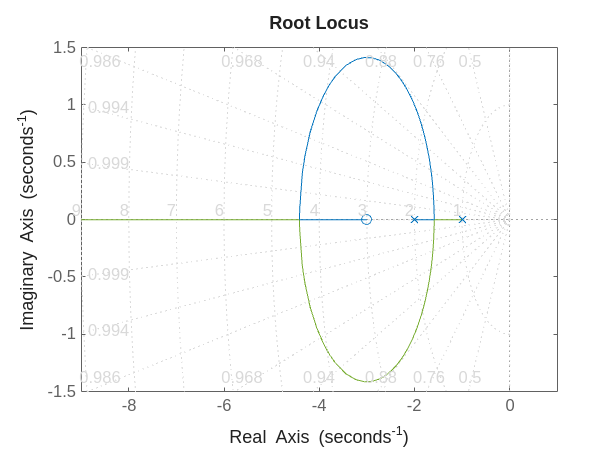

L = tf([1 3],conv([1 1],[1 2]));
figure(1);
clf();
rlocus(L)
sgrid()

## Choose two gains

ans = struct with fields:
         RiseTime: 1.607541257621792
    TransientTime: 2.660723888916171
     SettlingTime: 2.660723888916171
      SettlingMin: 0.298253582174624
      SettlingMax: 0.331020847386780
        Overshoot: 0
       Undershoot: 0
             Peak: 0.331020847386780
         PeakTime: 4.674316885476777


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.67e+00 + 4.67e-01i     9.63e-01       1.73e+00         6.01e-01    
 -1.67e+00 - 4.67e-01i     9.63e-01       1.73e+00         6.01e-01    


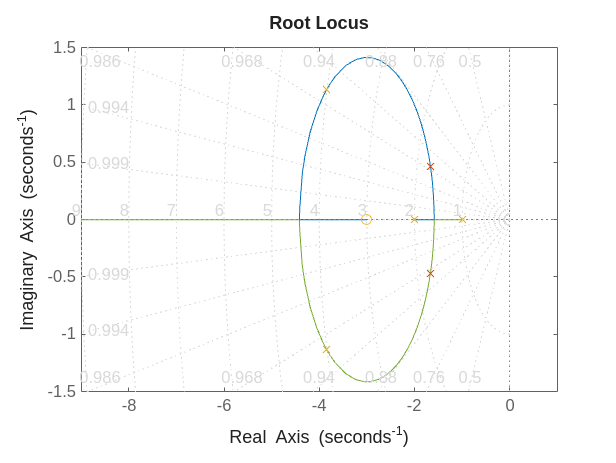

ans = struct with fields:
         RiseTime: 0.336750618748390
    TransientTime: 0.846613121837776
     SettlingTime: 0.846613121837776
      SettlingMin: 0.790109356264939
      SettlingMax: 0.893388660992998
        Overshoot: 2.011045687852953
       Undershoot: 0
             Peak: 0.893388660992998
         PeakTime: 0.813380708174473


                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -3.85e+00 + 1.13e+00i     9.60e-01       4.01e+00         2.60e-01    
 -3.85e+00 - 1.13e+00i     9.60e-01       4.01e+00         2.60e-01    


KK = [0.33, 4.7];

% Annotate rlocus and plot step responses
figure(2);
clf()
lstr={};
for ii = 1:length(KK)
    figure(1);
    hold on
    rlocus(L,KK(ii),'x');
    T = feedback(KK(ii)*L,1);
    stepinfo(T)
    damp(T)
    figure(2);
    step(T)
    lstr{ii} = sprintf('K=%.2f',KK(ii));
    hold on
end

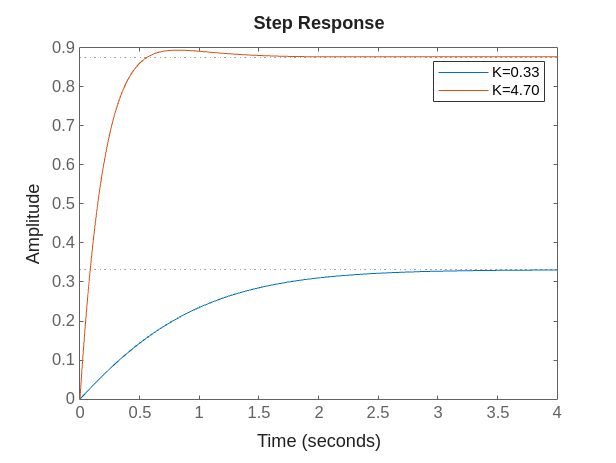

legend(lstr)